# Lab 2

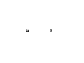

clear;
cla;


I = imread("Lab2\Filtering\van.tif");
sigma = 20;
a = 2*ceil(3*sigma) +1;

gauss_kern = fspecial("gaussian", [a a], sigma)

gauss_kern = 1.0e-03 *

    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0016    0.0017    0.0018    0.0019    0.0020    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0038
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0016    0.0017    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0027    0.0028    0.0030    0.0031    0.0033    0.0034    0.0036    0.0037    0.0039    0.0040    0

[S, HCOL, HROW] = isfilterseparable(gauss_kern)

S = logical
   1


HCOL =    -0.0002
   -0.0003
   -0.0003
   -0.0003
   -0.0004
   -0.0005
   -0.0005
   -0.0006
   -0.0007
   -0.0008


HROW =    -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0013   -0.0014   -0.0016   -0.0018   -0.0020   -0.0022   -0.0024   -0.0027   -0.0030   -0.0033   -0.0036   -0.0040   -0.0043   -0.0047   -0.0051   -0.0056   -0.0060   -0.0065   -0.0070   -0.0075   -0.0080   -0.0086   -0.0092   -0.0097   -0.0103   -0.0109   -0.0115   -0.0121   -0.0127   -0.0133   -0.0139   -0.0145   -0.0151   -0.0157   -0.0162   -0.0167   -0.0172


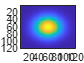


figure
imagesc(gauss_kern)


%decomposed
tic
result = conv2(HROW, HCOL, I);
toc 

Elapsed time is 0.005290 seconds.



%2d filtering
tic
result_full = imfilter(I, gauss_kern, a/2)

result_full = 534×566 uint8 matrix
   107   109   111   113   115   116   118   120   122   123   125   127   128   130   131   132   134   135   136   137   139   140   141   142   143   143   144   145   146   146   147   147   148   148   149   149   150   150   150   151   151   151   151   151   151   152   152   152   152   152
   109   111   113   115   117   119   120   122   124   126   127   129   131   132   134   135   137   138   139   140   142   143   144   145   146   147   147   148   149   150   150   151   151   152   152   153   153   153   154   154   154   154   155   155   155   155   155   155   155   155
   111   113   115   117   119   121   123   124   126   128   130   132   133   135   136   138   139   141   142   143   145   146   147   148   149   150   151   151   152   153   153   154   155   155   156   156   156   157   157   157   158   158   158   158   158   159   159   159   159   159
   113   115   117   119   121   123   125   127   129   130  

toc

Elapsed time is 0.013679 seconds.


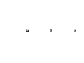


figure
subplot(1,3,1)
imshow(I)
hold on
subplot(1,3,2)
imshow(result, [])
subplot(1,3,3)
imshow(result_full, [])

clear;
sigma = 10;
a = 2*ceil(3*sigma) +1;
gauss_kern = fspecial("gaussian", [a a], sigma)

gauss_kern =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.

middle = gauss_kern(:,round(a/2))

middle =     0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0002


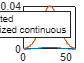


x = linspace(-3 * sigma, 3 * sigma, 61);
continuous_gauss = exp(-(x.^2) / (2 * sigma^2));
continuous_gauss_normalized = continuous_gauss / sum(continuous_gauss);

figure
plot(middle)
hold on 
%plot(continuous_gauss)
hold on
plot(continuous_gauss_normalized)
legend('generated', 'normalized continuous')

1.3

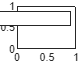

clear;
cla;


I = imread("Lab2\Filtering\wagon_shot_noise.png");